%% Create figure 1.
size_list=25

size_list = 25

c_gains=logspace(-2,3,size_list)

c_gains = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0012    0.0020    0.0032    0.0051    0.0083    0.0133    0.0215    0.0348    0.0562    0.0909    0.1468    0.2371    0.3831    0.6190    1.0000


tau_list=logspace(-4,0,size_list)

tau_list =     0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010    0.0015    0.0022    0.0032    0.0046    0.0068    0.0100    0.0147    0.0215    0.0316    0.0464    0.0681    0.1000    0.1468    0.2154    0.3162    0.4642    0.6813    1.0000


m_e=0.1

m_e = 0.1000

k_e_list=logspace(-2,3,size_list)

k_e_list = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0012    0.0020    0.0032    0.0051    0.0083    0.0133    0.0215    0.0348    0.0562    0.0909    0.1468    0.2371    0.3831    0.6190    1.0000


b_e=0.1

b_e = 0.1000

plot_list=[]


plot_list =

     []



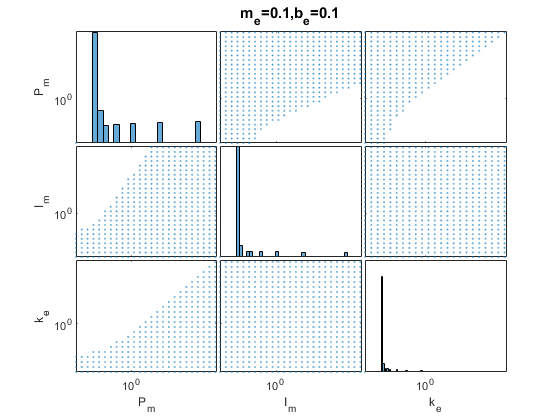

for i=1:length(c_gains)
    for j=1:length(c_gains)
        for k=1:length(k_e_list)
            %for l=1:length(m_e_list)
                P_m=c_gains(i);
                I_m=c_gains(j);
                k_e=k_e_list(k);
            %    m_e=k_e_list(l);
                passivityCheck;
                if passivity==1
                    plot_list=[plot_list;P_m I_m k_e];
                end
%         plot_k_e(i,j)=eval(k_e_max);
%         plot_m_e(i,j)=eval(m_e_max);
%         plot_routh(i,j)=eval(eps1);
%         plot_d_4(i,j)=eval(d_4);
%         plot_d_6(i,j)=eval(d_6);
%         plot_d_8(i,j)=eval(d_8);
         %   end
        end
       
    end
end
[h,ax] = plotmatrix(plot_list(:,[1,2,3])); % create a 4 x 4 matrix of plots
labels = {'P_{m}' 'I_{m}' 'k_{e}' };

set(ax, 'YScale', 'log')
set(ax, 'XScale', 'log')
title('m_e=0.1,b_e=0.1')
for i = 1:3                                  % label the plots
  xlabel(ax(3,i), labels{i},'FontSize',15);
  ylabel(ax(i,1), labels{i},'FontSize',15);
end